**PART 5 MODER CONTROL**

Flight control design: altitude and speed u tracking problem.

State-space model: Longitudinal linearized model.

Design requirements: The correct tracking of a command r1 = altitude [m], and the correct tracking of a command r2 = speed [m/s] simultaneously.

Modern Control Method: LQT 

clear
load LongMatsAlpha.mat
Ue = 67;
%A_long(2,2) = A_long(2,2)/Ue;

Present $A_{\textrm{long}}$ and $B_{\textrm{long}}$:

vpa(A_long,5)

$$ans = \left(\begin{array}{cccc} -0.045313 & -3.8266 & 0 & -9.81\\ -0.0043318 & -2.063 & 0.97067 & 0\\ 0.011159 & -14.089 & -6.8941 & 0\\ 0 & 0 & 1.0 & 0 \end{array}\right)$$

vpa(B_long,5)

$$ans = \left(\begin{array}{cc} 0 & 1.7658\\ -0.20116 & 0\\ -34.997 & 0\\ 0 & 0 \end{array}\right)$$

Now we need to include the altitude based on the following expression:


$$\dot{h} =U_e \left(\theta -\alpha \right)$$


A_long(1:4,5) = zeros(4,1);
A_long(5,1:5) = [0,-Ue,0,Ue,0]

A_long =    -0.0453   -3.8266         0   -9.8100         0
   -0.0043   -2.0630    0.9707         0         0
    0.0112  -14.0892   -6.8941         0         0
         0         0    1.0000         0         0
         0  -67.0000         0   67.0000         0


B_long = [B_long;[0,0]]

B_long =          0    1.7658
   -0.2012         0
  -34.9969         0
         0         0
         0         0


A1_long = A_long;
B1_long = B_long;
C1_long  = eye(5);
D1_long  = zeros(5,2);

These are associated to state $x={\left\lbrack u,\alpha ,q,\theta ,h\right\rbrack }^T$ and $u={\left\lbrack \delta_e ,\delta_p \right\rbrack }^T$. For this design we need to include both throttle control and elevator control. We use:


$$\delta_e =\frac{1}{T_e s+1}u_e$$



$$\delta_p =\frac{1}{T_p s+1}u_p$$



$$T_e =0\ldotp 1,T_p =3\ldotp 5$$


First we incorporate elevator dynamics in our matrix:

T_e = 0.1;
T_p = 3.5;
A_long(1:5,6) = B_long(:,1);
A_long(6,1:6) = [0,0,0,0,0,-1/T_e]

A_long =    -0.0453   -3.8266         0   -9.8100         0         0
   -0.0043   -2.0630    0.9707         0         0   -0.2012
    0.0112  -14.0892   -6.8941         0         0  -34.9969
         0         0    1.0000         0         0         0
         0  -67.0000         0   67.0000         0         0
         0         0         0         0         0  -10.0000


Next, include throttle dynamics:

A_long(1:6,7) = [B_long(:,2);0]

A_long =    -0.0453   -3.8266         0   -9.8100         0         0    1.7658
   -0.0043   -2.0630    0.9707         0         0   -0.2012         0
    0.0112  -14.0892   -6.8941         0         0  -34.9969         0
         0         0    1.0000         0         0         0         0
         0  -67.0000         0   67.0000         0         0         0
         0         0         0         0         0  -10.0000         0


A_long(7,1:7) = [0,0,0,0,0,0,-1/T_p]

A_long =    -0.0453   -3.8266         0   -9.8100         0         0    1.7658
   -0.0043   -2.0630    0.9707         0         0   -0.2012         0
    0.0112  -14.0892   -6.8941         0         0  -34.9969         0
         0         0    1.0000         0         0         0         0
         0  -67.0000         0   67.0000         0         0         0
         0         0         0         0         0  -10.0000         0
         0         0         0         0         0         0   -0.2857


B_long = [0,0;0,0;0,0;0,0;0,0;1/T_e,0;0,1/T_p]

B_long =          0         0
         0         0
         0         0
         0         0
         0         0
   10.0000         0
         0    0.2857


So far, the state is ${x=\left\lbrack u,\alpha \;,q,\theta ,{h,\delta }_e ,\delta_p \right\rbrack }^T$ and the input $u={\left\lbrack u_e ,u_p \right\rbrack }^T$

Next, we need commands for tracking altitude and speed and their state following:


$$\dot{\epsilon} =\left\lbrack \begin{array}{c}
\dot{\epsilon_1 } \\
\dot{\epsilon_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
r_1 -h\\
r_2 -u
\end{array}\right\rbrack$$


A_long(1:7,8) = zeros(7,1);
A_long(8,1:8) = [0,0,0,0,-1,0,0,0]

A_long =    -0.0453   -3.8266         0   -9.8100         0         0    1.7658         0
   -0.0043   -2.0630    0.9707         0         0   -0.2012         0         0
    0.0112  -14.0892   -6.8941         0         0  -34.9969         0         0
         0         0    1.0000         0         0         0         0         0
         0  -67.0000         0   67.0000         0         0         0         0
         0         0         0         0         0  -10.0000         0         0
         0         0         0         0         0         0   -0.2857         0
         0         0         0         0   -1.0000         0         0         0


B_long = [B_long;[0,0]];

So far, the state is ${x=\left\lbrack u,\alpha \;,q,\theta ,\delta_e ,\delta_p ,h,\epsilon_1 \right\rbrack }^T$ and the input $u={\left\lbrack u_e ,u_p \right\rbrack }^T$

A_long(1:8,9) = zeros(8,1);
A_long(9,1:9) = [-1,0,0,0,0,0,0,0,0]

A_long =    -0.0453   -3.8266         0   -9.8100         0         0    1.7658         0         0
   -0.0043   -2.0630    0.9707         0         0   -0.2012         0         0         0
    0.0112  -14.0892   -6.8941         0         0  -34.9969         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0  -67.0000         0   67.0000         0         0         0         0         0
         0         0         0         0         0  -10.0000         0         0         0
         0         0         0         0         0         0   -0.2857         0         0
         0         0         0         0   -1.0000         0         0         0         0
   -1.0000         0         0         0         0         0         0         0         0


B_long = [B_long;[0,0]]

B_long =          0         0
         0         0
         0         0
         0         0
         0         0
   10.0000         0
         0    0.2857
         0         0
         0         0


So far, the state is ${x=\left\lbrack u,\alpha \;,q,\theta ,{h,\delta }_e ,\delta_p ,\epsilon_1 ,\epsilon_2 \right\rbrack }^T$ and the input $u={\left\lbrack u_e ,u_p \right\rbrack }^T$

Now, E matrix for commands ${\left\lbrack r_1 ,r_2 \right\rbrack }^T$:

E = [zeros(7,2);[1,0];[0,1]]

E =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     1     0
     0     1


Next, H matrix:

H = [0,0,0,0,1,0,0,0,0;1,0,0,0,0,0,0,0,0];
Q = H' * H;
Q(8,8) = 0.001;
Q(9,9) = 0.1;
Q = 0.01*Q;
R = 10000;
[K,P] = lqr(A_long,B_long,Q,R);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Matrices for SIMULINK
K_eps_long  = K(:,8:9);
K_deltas_long  = K(:,6:7);
K_lqr_long  = K(:,1:5);
NoiseP = 1e-6*ones(5,1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Observations for step input:

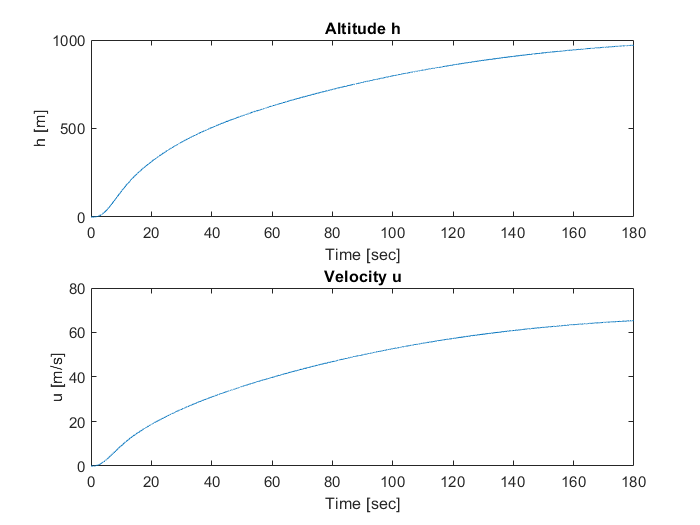

Ac = A_long-B_long*K;
Bc = E;
sys_cl = ss(Ac,Bc,H,0);
t = 0:0.01:180;
opt = stepDataOptions;
opt.StepAmplitude = [1000,67]; % Input command of r1 = 1000 [m] and r2=10 [m/s]
[y1,t1,x1] = step(sys_cl,t,opt);

figure
subplot(2,1,1)
y_h1 = y1(:,1,1);
plot(t1,y_h1)
title('Altitude h')
xlabel('Time [sec]')
ylabel('h [m]')
subplot(2,1,2)
y_u1 = y1(:,2,2);
plot(t1,y_u1)
title('Velocity u')
xlabel('Time [sec]')
ylabel('u [m/s]')

Inclusion of Wind Gust Process Noise and measurement noise:

% From notes and Stevens Book
C = eye(9);
L = 3.49;
sig = 10;
A_w = [0,1;-1/(L^2),-2/(L)];
B_w = [0;1];
C_w = sig * sqrt(6/L) * [1/(L*sqrt(3)),1];
G = [0;0.00203;-0.00164;0;0;0;0;0;0]; % Consistent with number of states

Create augmented system with wind states ${x=\left\lbrack u,\alpha \;,q,\theta ,h,\delta_e ,\delta_p ,\epsilon_1 ,\epsilon_2 ,x_{\textrm{w1}} ,x_{\textrm{w2}} \right\rbrack }^T$:

A_aug = [A_long,G*C_w;zeros(2,9),A_w];
B_aug = [B_long;zeros(2)];
E_aug = [E;zeros(2)];
G_aug = [zeros(9,1);B_w];
H_aug = [H,zeros(2)];
C_aug = [C,zeros(9,2)];

Same as before, solve for LQT:

Q = H_aug' * H_aug;
Q(8,8) = 0.001;
Q(9,9) = 0.001;
Q = 0.001*Q;
R = eye(2);
[K1,P] = lqr(A_aug,B_aug,Q,R);
K1 = inv(R)*B_aug'*P / C_aug;

Now include observer:

Q = 1;
R = 1/20 * eye(9); %Measurement Noise
R(8,8) = 1;
R(9,9) = 1;
[K,P] =lqr(A_aug',C_aug',G_aug*Q*G_aug',R);
L = K';

Closed loop system with observer:

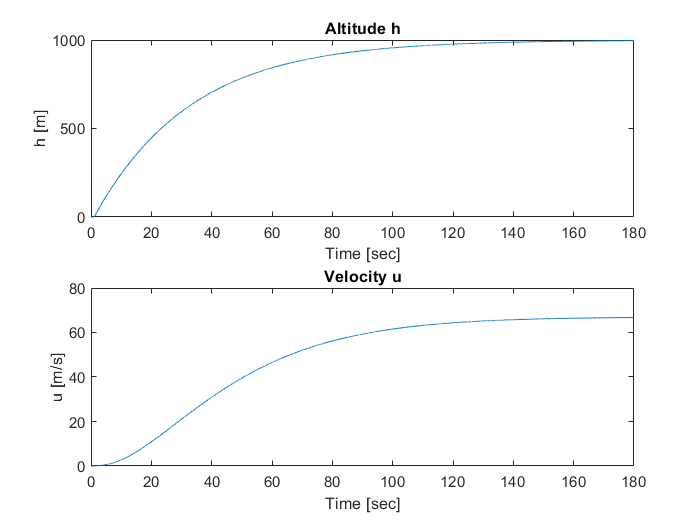

A_cl = [A_aug - B_aug*K1*C_aug, B_aug*K1*C_aug;zeros(11),A_aug - L*C_aug];
B_cl = [E_aug;zeros(11,2)];
H_cl = [H_aug,zeros(2,11)];
C_cl = [C_aug,zeros(9,11)];
sys_cl = ss(A_cl,B_cl,H_cl,0);
t = 0:0.01:180;
opt = stepDataOptions;
opt.StepAmplitude = [1000,67]; % Input command of r1 = 1000 [m] and r2=10 [m/s]
[y1,t1,x1] = step(sys_cl,t,opt);

figure
subplot(2,1,1)
y_h1 = y1(:,1,1);
plot(t1,y_h1)
title('Altitude h')
xlabel('Time [sec]')
ylabel('h [m]')
subplot(2,1,2)
y_u1 = y1(:,2,2);
plot(t1,y_u1)
title('Velocity u')
xlabel('Time [sec]')
ylabel('u [m/s]')

COMPARE ACTUAL STATE AND ESTIMATED STATE THROUGH ERROR STATE:

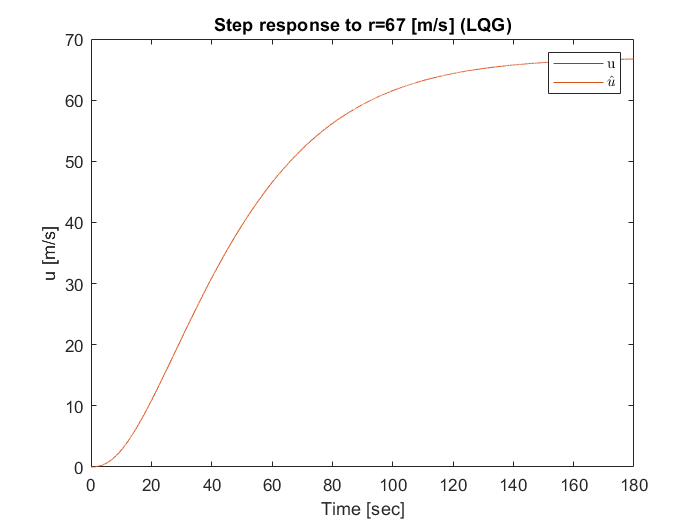

st1 = y_u1;
st1_err = x1(:,12,1);
est_st1 = st1 - st1_err;
figure
plot(t1,st1,t1,est_st1)
legend({'u','$\hat{u}$'},'Interpreter','latex')
xlabel('Time [sec]')
ylabel('u [m/s]')
title('Step response to r=67 [m/s] (LQG)')

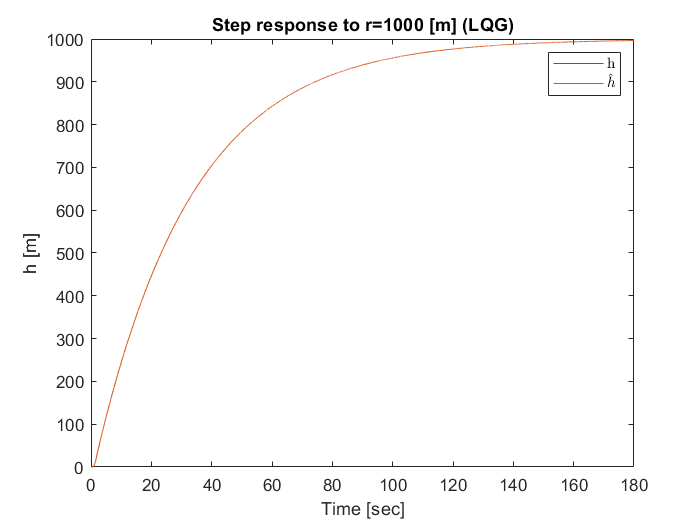

st1 = y_h1;
st1_err = x1(:,16,1);
est_st1 = st1 - st1_err;
figure
plot(t1,st1,t1,est_st1)
legend({'h','$\hat{h}$'},'Interpreter','latex')
xlabel('Time [sec]')
ylabel('h [m]')
title('Step response to r=1000 [m] (LQG)')